% 本文件中使用cell数组构建的矩阵，存储生物体来进行有地理关系的博弈，故为cell_mat.mlx
clear;close all;clc;

% 博弈的参数
max_migrate_num = 5; % 新生个体的最大迁移次数
profit = [ 18,18; -5,-5 ; 20,-10 ; -10,20 ]; % 收益矩阵：第一组是都合作的收益，第二组是都竞争的收益，第三组是A竞争、B合作的收益，第四组是A合作、B竞争的收益
round_num = 40;
map_sz = 100; % 地图大小

% A种群的参数
resourceA = 100;
max_resA = 250;
lifespanA = 30;
op_probA = 0.8;
A_initnum = 5; % 初始指定的种群数量

% B种群的参数
resourceB = 100;
max_resB = 200;
lifespanB = 15;
op_probB = 0.6;
B_initnum = 5;

% C种群的参数
resourceC = 100;
max_resC = 200;
lifespanC = 15;
op_probC = 0.4;
C_initnum = 5;

% 建立地图

o_A = Organism("A",resourceA,max_resA,lifespanA,op_probA); % 用于初始化链表的第一个生物
org_A = LinkedList(o_A);
for i = 1:(A_initnum-1)
    o = Organism("A",resourceA,max_resA,lifespanA,op_probA);
    org_A.append(o);
end

o_B = Organism("B",resourceB,max_resB,lifespanB,op_probB);
org_B = LinkedList(o_B);
for i = 1:(B_initnum-1)
    o = Organism("B",resourceB,max_resB,lifespanB,op_probB);
    org_B.append(o);
end

o_C = Organism("C",resourceC,max_resC,lifespanC,op_probC);
org_C = LinkedList(o_C);
for i = 1:(C_initnum-1)
    o = Organism("C",resourceC,max_resC,lifespanC,op_probC);
    org_C.append(o);
end

org_mat = cell(map_sz,map_sz);
% 随机选取，初始安排在不同的行
% iA = randi([10,90],1);
% jA = randi([1,map_sz-A_initnum+1],1);
% 
% iB = randi([10,90],1);
% while iB == iA
%     iB = randi([1, 100], 1, 1);
% end
% jB = randi([1,map_sz-B_initnum+1],1);
% 
% iC = randi([10,90],1);
% while iC == iA || iC == iB
%     iC = randi([1, 100], 1, 1);
% end
% jC = randi([1,map_sz-C_initnum+1],1);

% 为了让各种群可以早点相遇而手动安排出生点
iA = 50;
jA = 50;

iB = 40;
jB = 40;

iC = 60;
jC = 60;



% 装进地图中
for k = 0:A_initnum-1
    org_mat{iA,jA+k} = org_A.get(k+1);
end
for k = 0:B_initnum-1
    org_mat{iB,jB+k} = org_B.get(k+1);
end
for k = 0:C_initnum-1
    org_mat{iC,jC+k} = org_C.get(k+1);
end

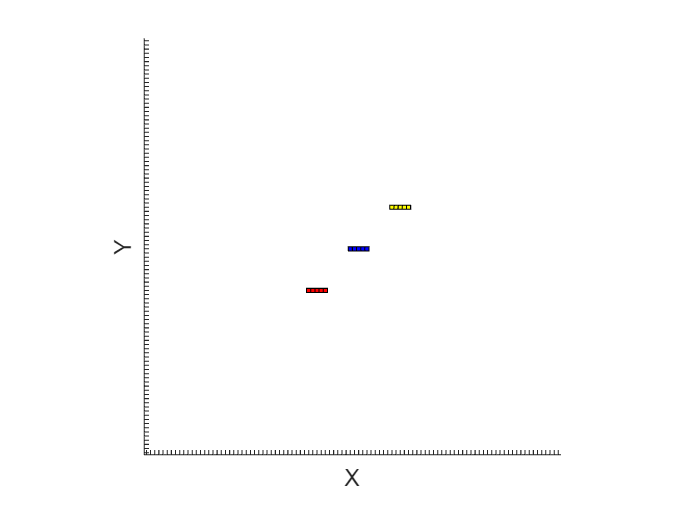

% 博弈
g = Game(profit,round_num);
g.draw_mat(org_mat)

迭代轮次1


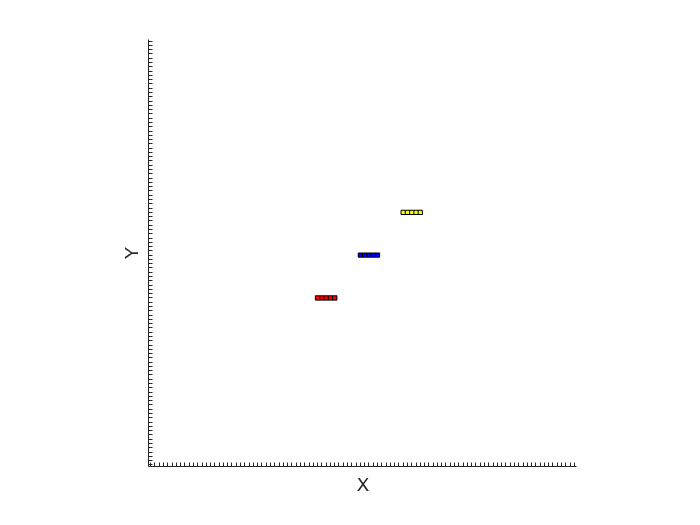

迭代轮次2


迭代轮次3


迭代轮次4


迭代轮次5


迭代轮次6


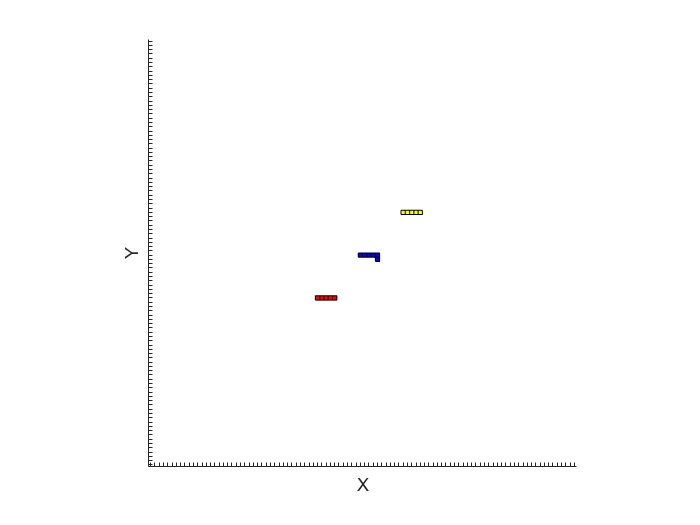

迭代轮次7


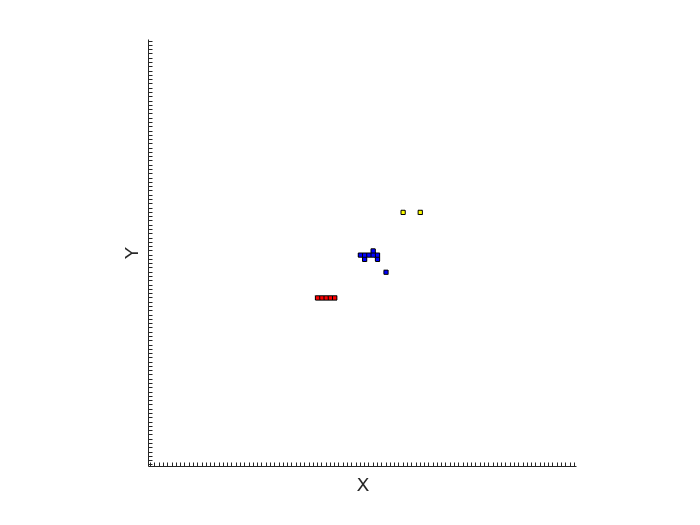

迭代轮次8


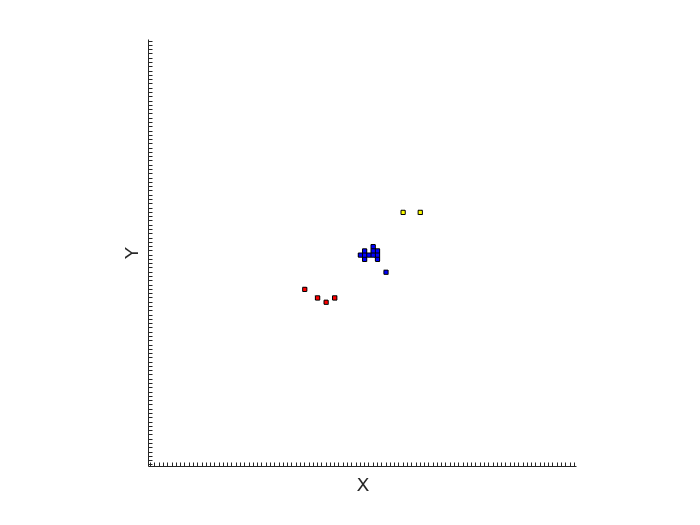

迭代轮次9


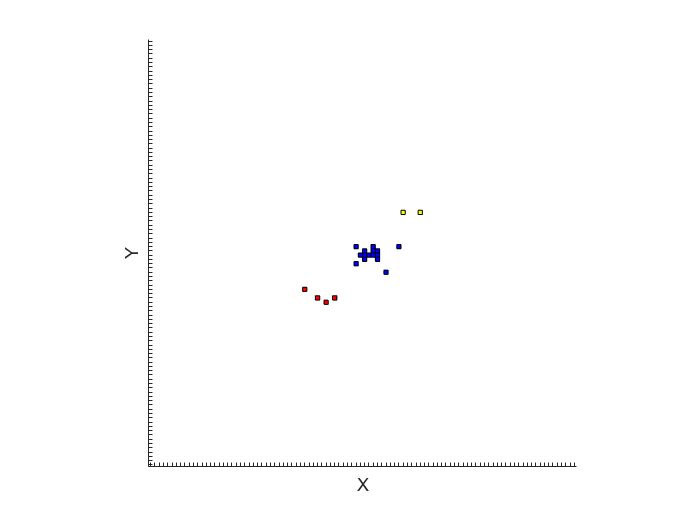

迭代轮次10


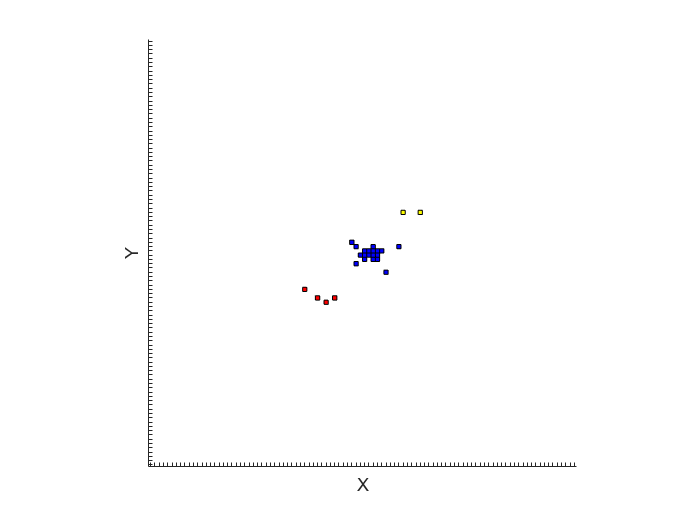

迭代轮次11


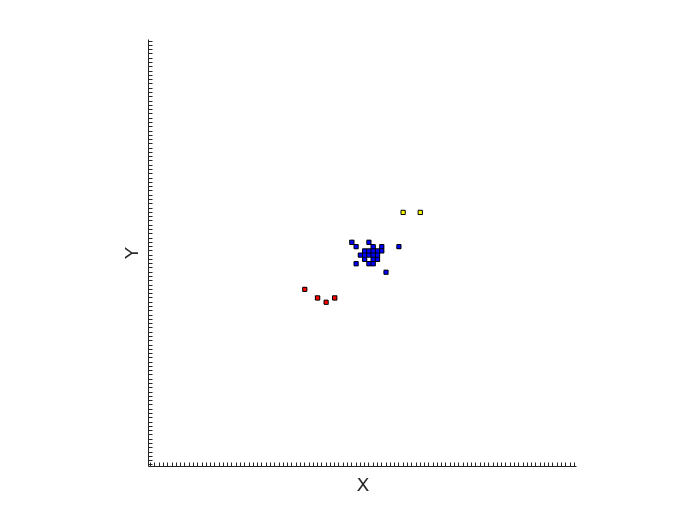

迭代轮次12


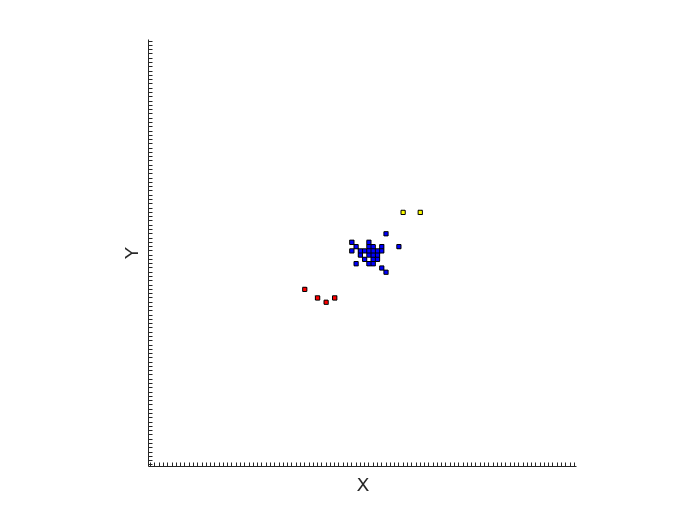

迭代轮次13


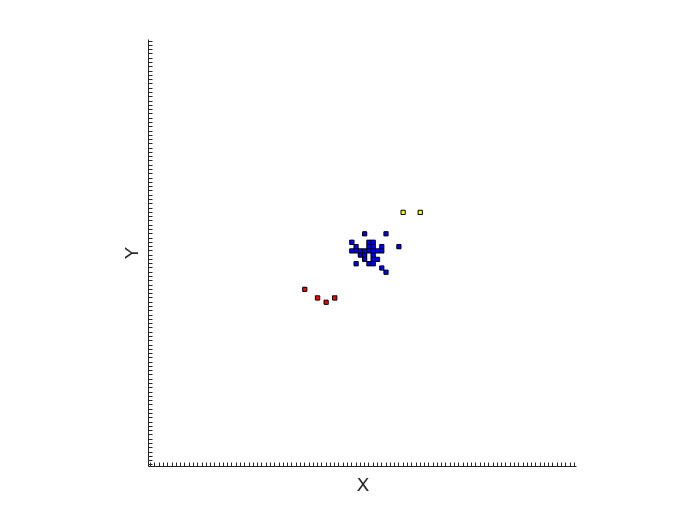

迭代轮次14


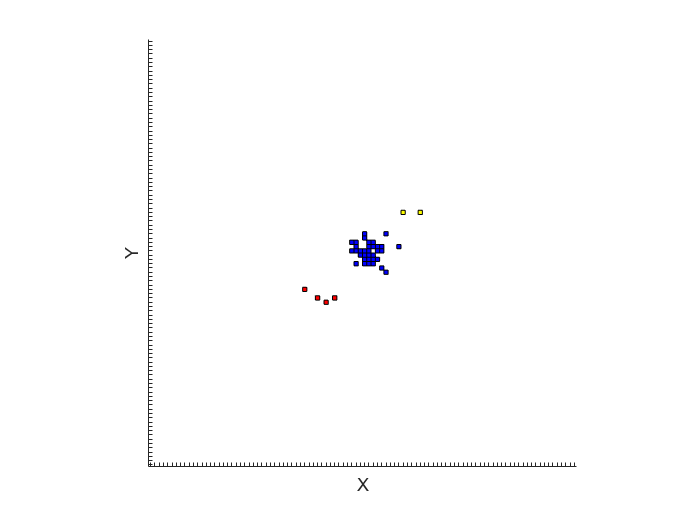

迭代轮次15


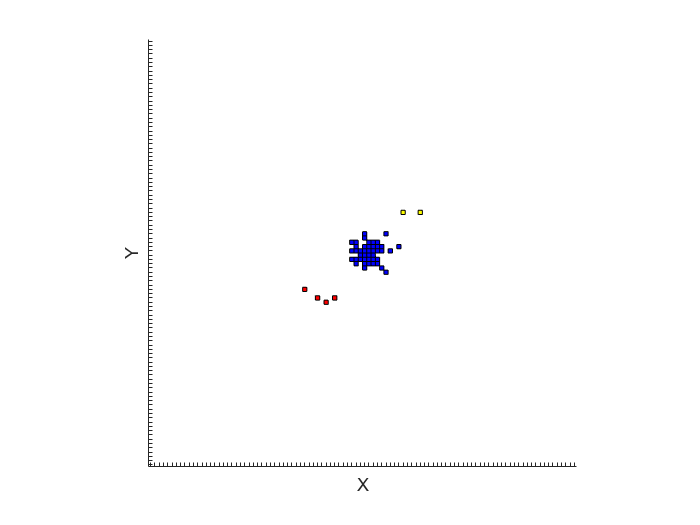

迭代轮次16


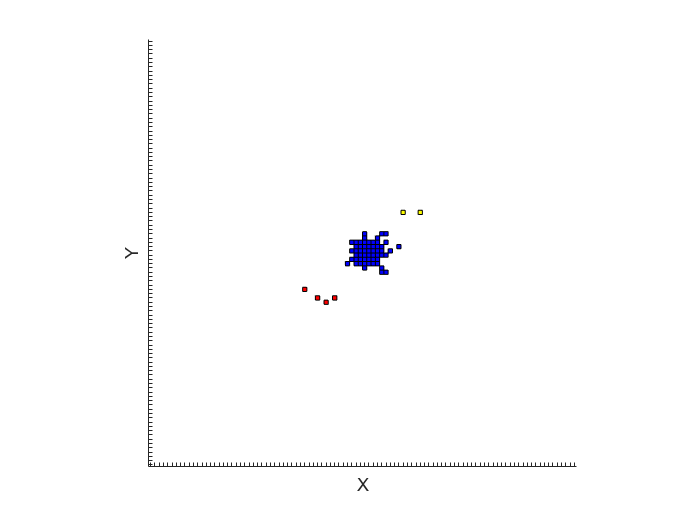

迭代轮次17


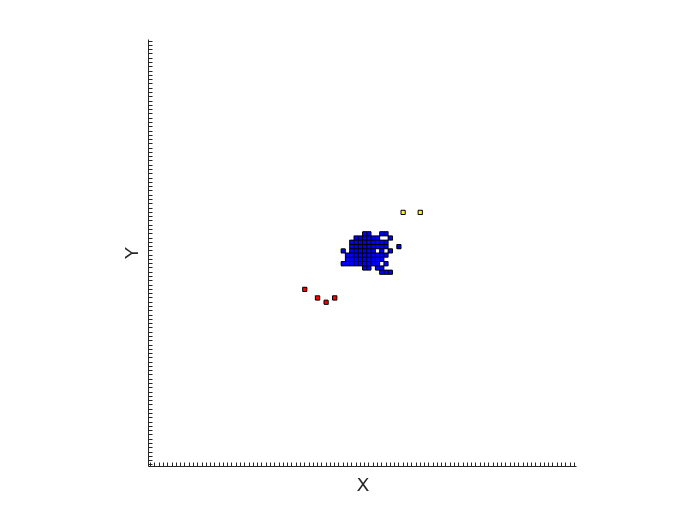

迭代轮次18


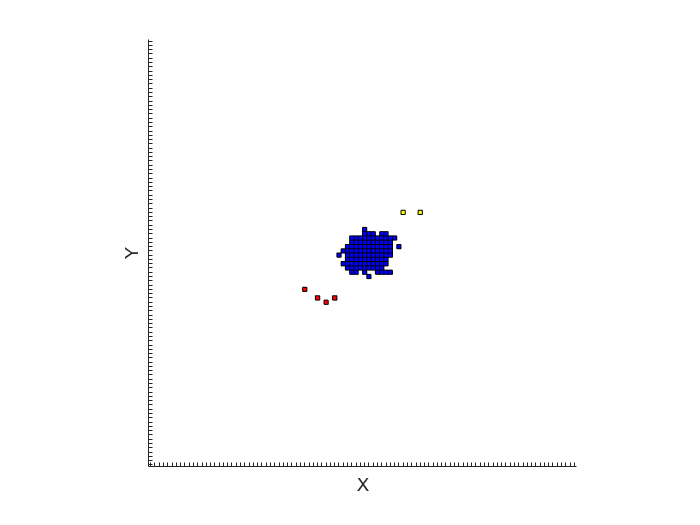

迭代轮次19


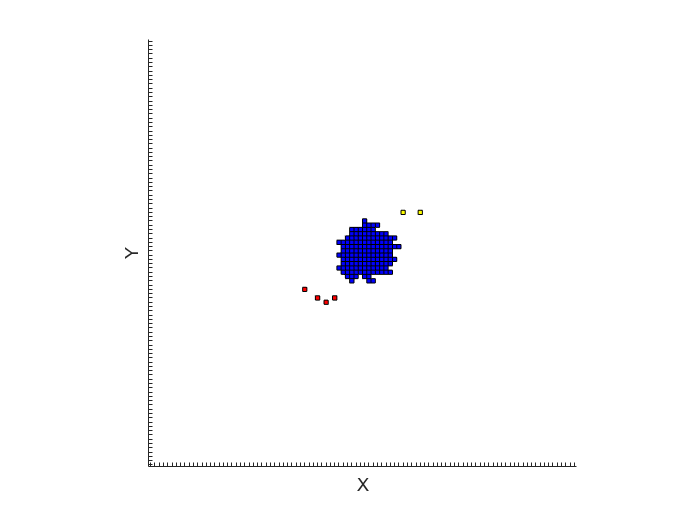

迭代轮次20


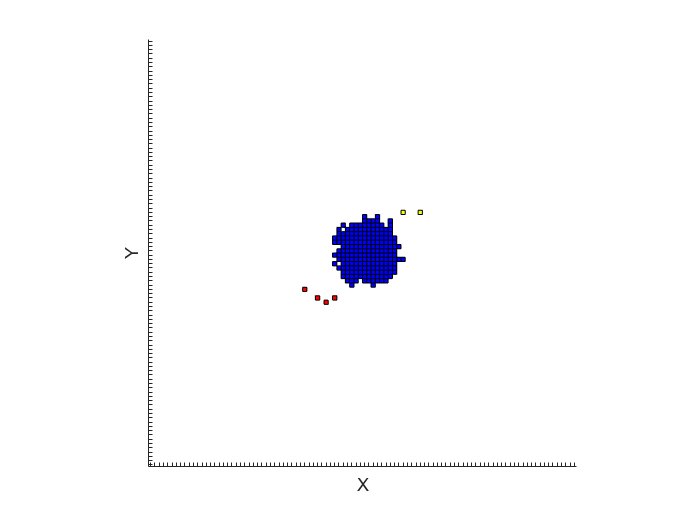

迭代轮次21


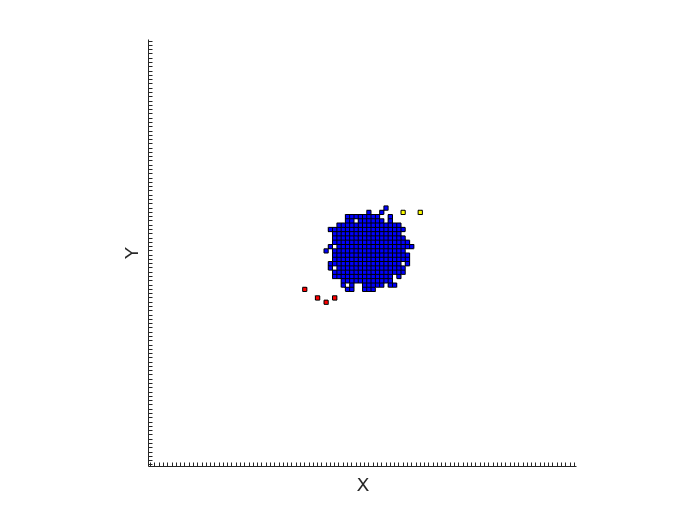

迭代轮次22


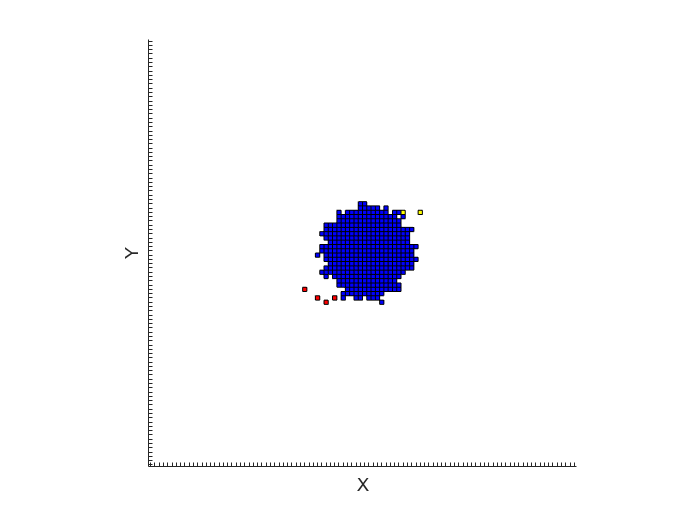

迭代轮次23


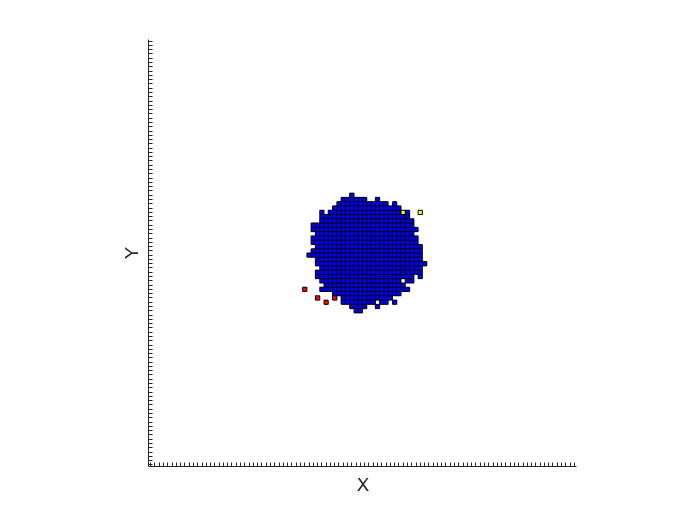

迭代轮次24


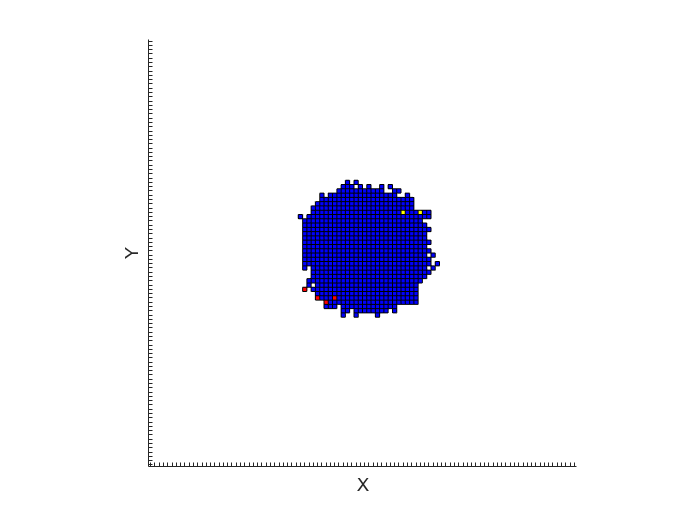

迭代轮次25


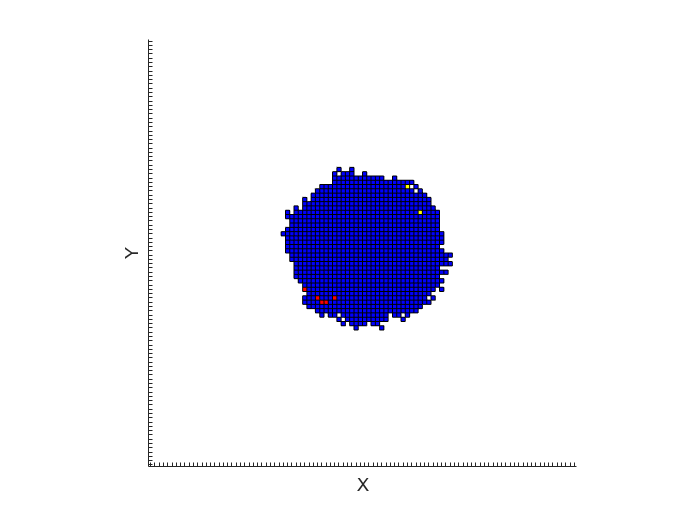

迭代轮次26


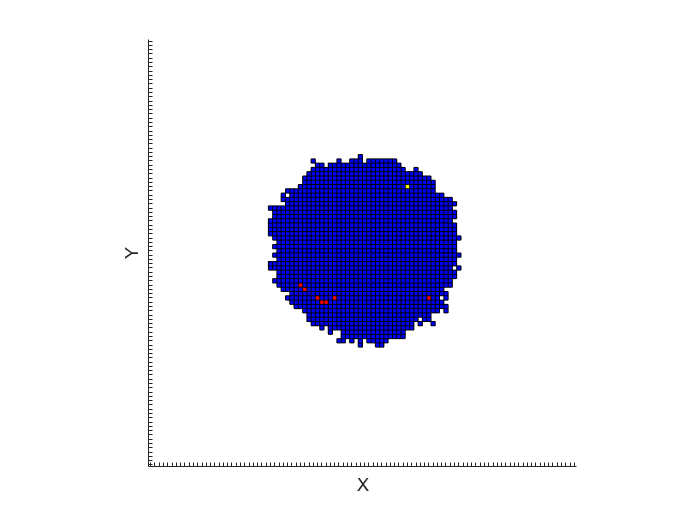

迭代轮次27


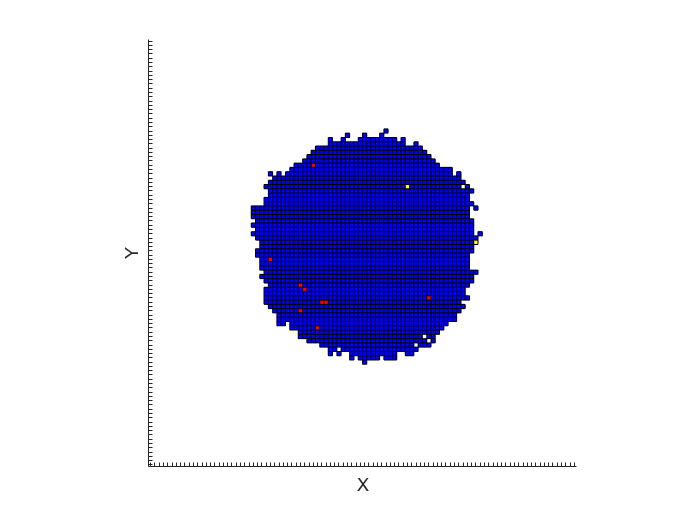

迭代轮次28


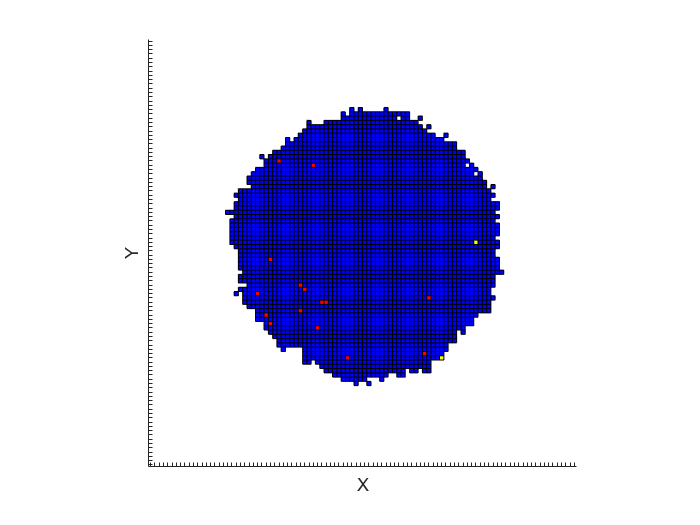

迭代轮次29


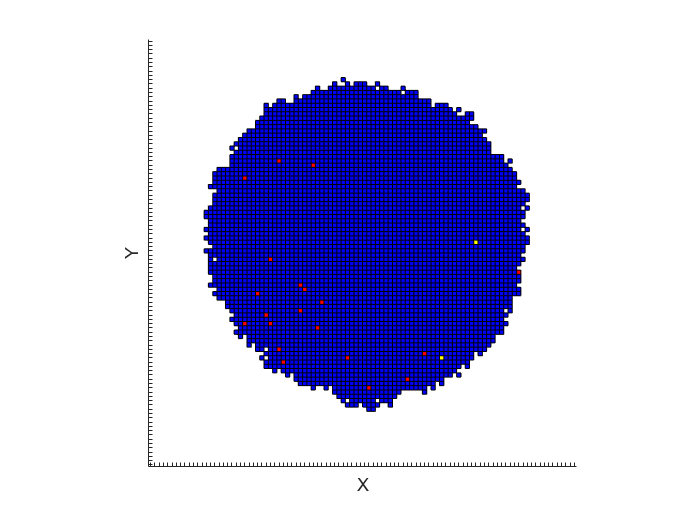

迭代轮次30


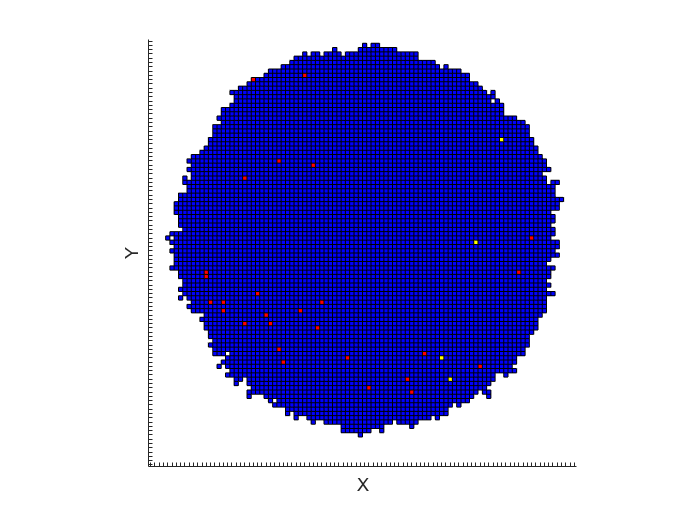

迭代轮次31


[kind_map_array,org_mat] = g.play_mat(org_mat,max_migrate_num);

% 博弈结果输出
kind_map_1 = kind_map_array{1};
kind = string(keys(kind_map_1)); % 获取所有键（种类）
kind_num = length(kind); % 获取种类的个数

amount_mat = zeros(kind_num); % 新建一个存储种群数量的矩阵，第i列对应第i个种群（键）
for i = 1:length(kind_map_array)
    kind_map = kind_map_array{i};
    amount = [];
    for j = 1:kind_num
        a = kind_map(kind(j)); % 获取所有值（每轮迭代各种群的数量），并将其转换为数组
        amount = [amount,a];
    end
    amount_mat = [amount_mat;amount];
end
amount_mat = amount_mat(4:end, :); % 删除前两行（初始化的全零行）

% 绘图
x = 1:round_num;
for i = 1:kind_num
    y = amount_mat(:,i); % 取出每一列（各种群的数量）
    y = y';
    plot(x,y)
    hold on
end
xlabel("迭代轮次")
ylabel("种群数量")
legend(kind(1),kind(2),kind(3))